# Aula 14 - Alocação de polos

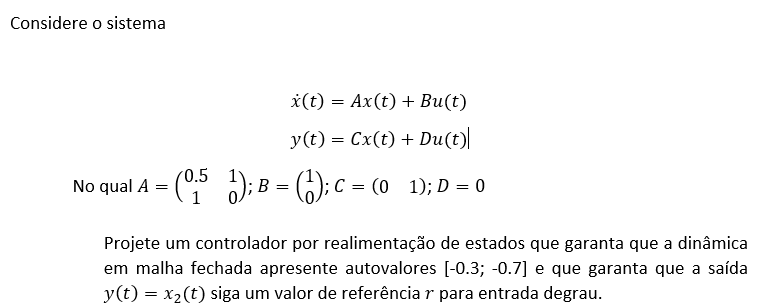

clear;clc;close all;
A=[0.5,1;1,0];
B=[1;0];
C=[0,1];
D=0;

A matriz A é 2x2, então o sistema é de segunda ordem ( $n=2$ ). 

Além disso, por B vemos que o sistema tem uma única entrada e por C vemos que o sistema tem uma única saída, o que indica que é um sistema SISO.

Mo=obsv(A,C);
Mc=ctrb(A,B);
rank(Mo)

ans = 2

rank(Mc)

ans = 2

Como $rank(M_o)$ e $rank(M_c)$ são iguais a $n$, o sistema é controlável e observável.

"Autovalores [-0.3,-0.7]" significa que esses são os polos dominantes e "saída siga um valor de referência r para entrada degrau" significa erro nulo em em regime.

pk=[-0.3;-0.7]; %polos desejados
K=place(A,B,pk)

K =     1.5000    1.2100


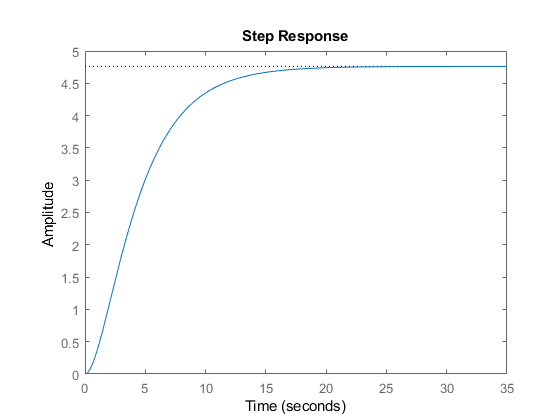

Kr=1;
Amf=A-B*K;
Bmf=B*Kr;
Cmf=C-D*K;
Dmf=D*Kr;
sys_mf=ss(Amf,Bmf,Cmf,Dmf);
step(sys_mf)

Kr=1/dcgain(sys_mf)

Kr = 0.2100

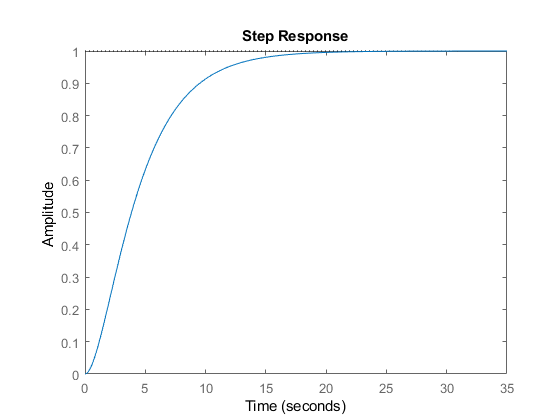

Amf=A-B*K;
Bmf=B*Kr;
Cmf=C-D*K;
Dmf=D*Kr;
sys_mf=ss(Amf,Bmf,Cmf,Dmf);
step(sys_mf)

damp(sys_mf)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -3.00e-01     1.00e+00       3.00e-01         3.33e+00    
 -7.00e-01     1.00e+00       7.00e-01         1.43e+00    
